load('proj5Data_qfi.mat');

intLimits_v = [min(image_3d(:)), max(image_3d(:))];
figure
for index = 1:nTimes
    imagesc(squeeze(image_3d(:, :, index)),intLimits_v);
    axis image
    axis off
    colormap(gray)
    title(['Time points: ', num2str(index)])
    drawnow
    mov(index) = getframe;
end
fps = 8;          % frames per second.
nReps = 4;    % number of repetitions.
movie(mov, nReps, fps)

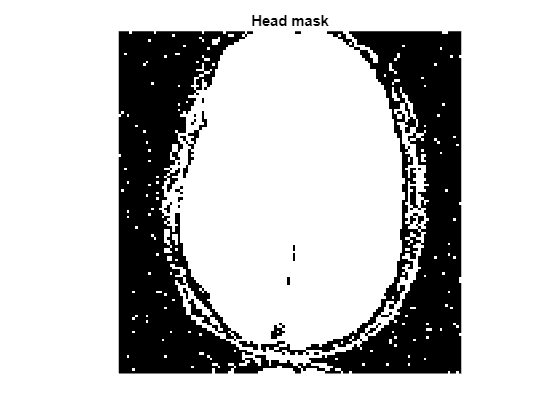

% Create head mask
imageMax = max(image_3d(:));
image_m = squeeze(image_3d(:, :, 1));
headMask_m = (image_m > 0.1*imageMax);
figure
imagesc(headMask_m)
colormap(gray)
axis image
axis off
title('Head mask')

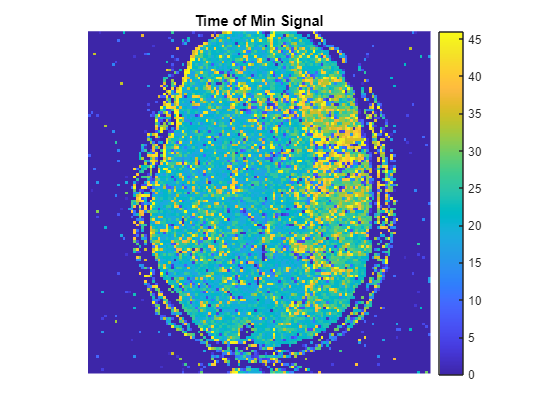

timeOfMin_m = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1: nCols
        if (headMask_m(row, col) == 1)
            [minSignal, timeOfMin_m(row,col)] = min(image_3d(row, col, :), [], 3);
        end
    end
end 
figure
imagesc(timeOfMin_m)
colorbar
axis image
axis off
title('Time of Min Signal')

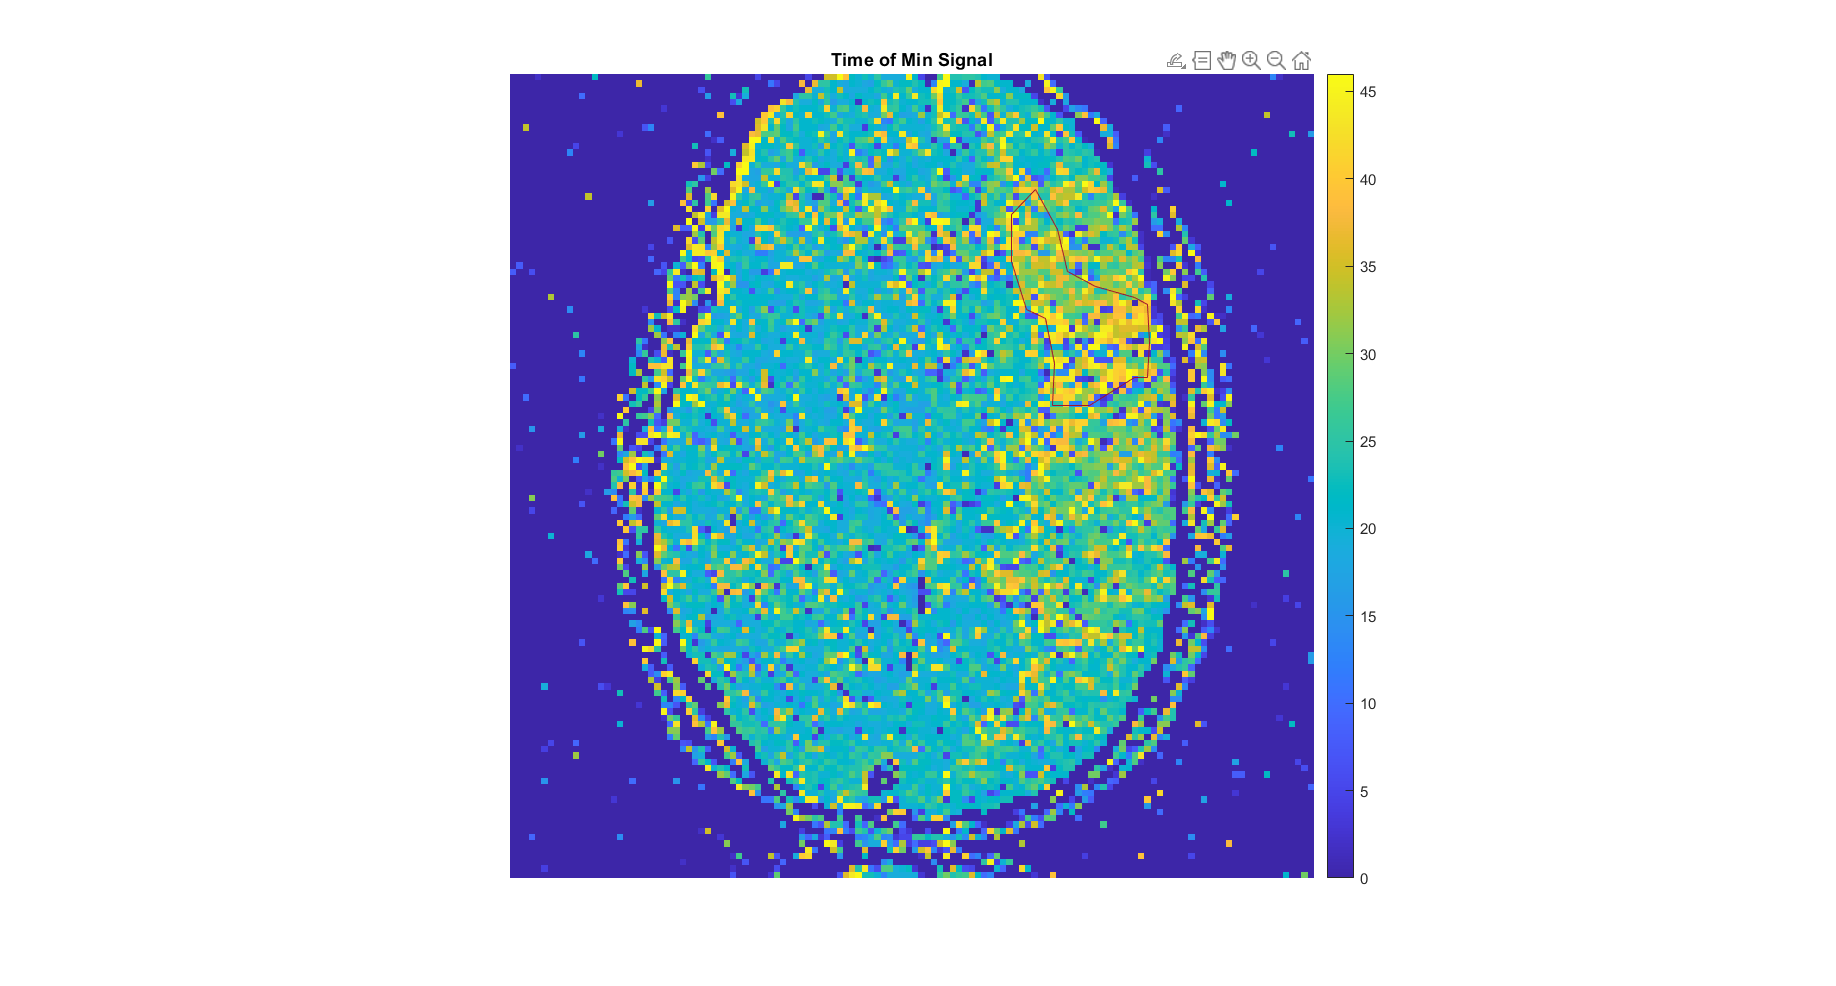

[slowRoiMask_m, x_v, y_v] = roipoly ;
slowRoiMask_m = slowRoiMask_m .* headMask_m;
line(x_v, y_v, 'Color', '#A2142F') ;

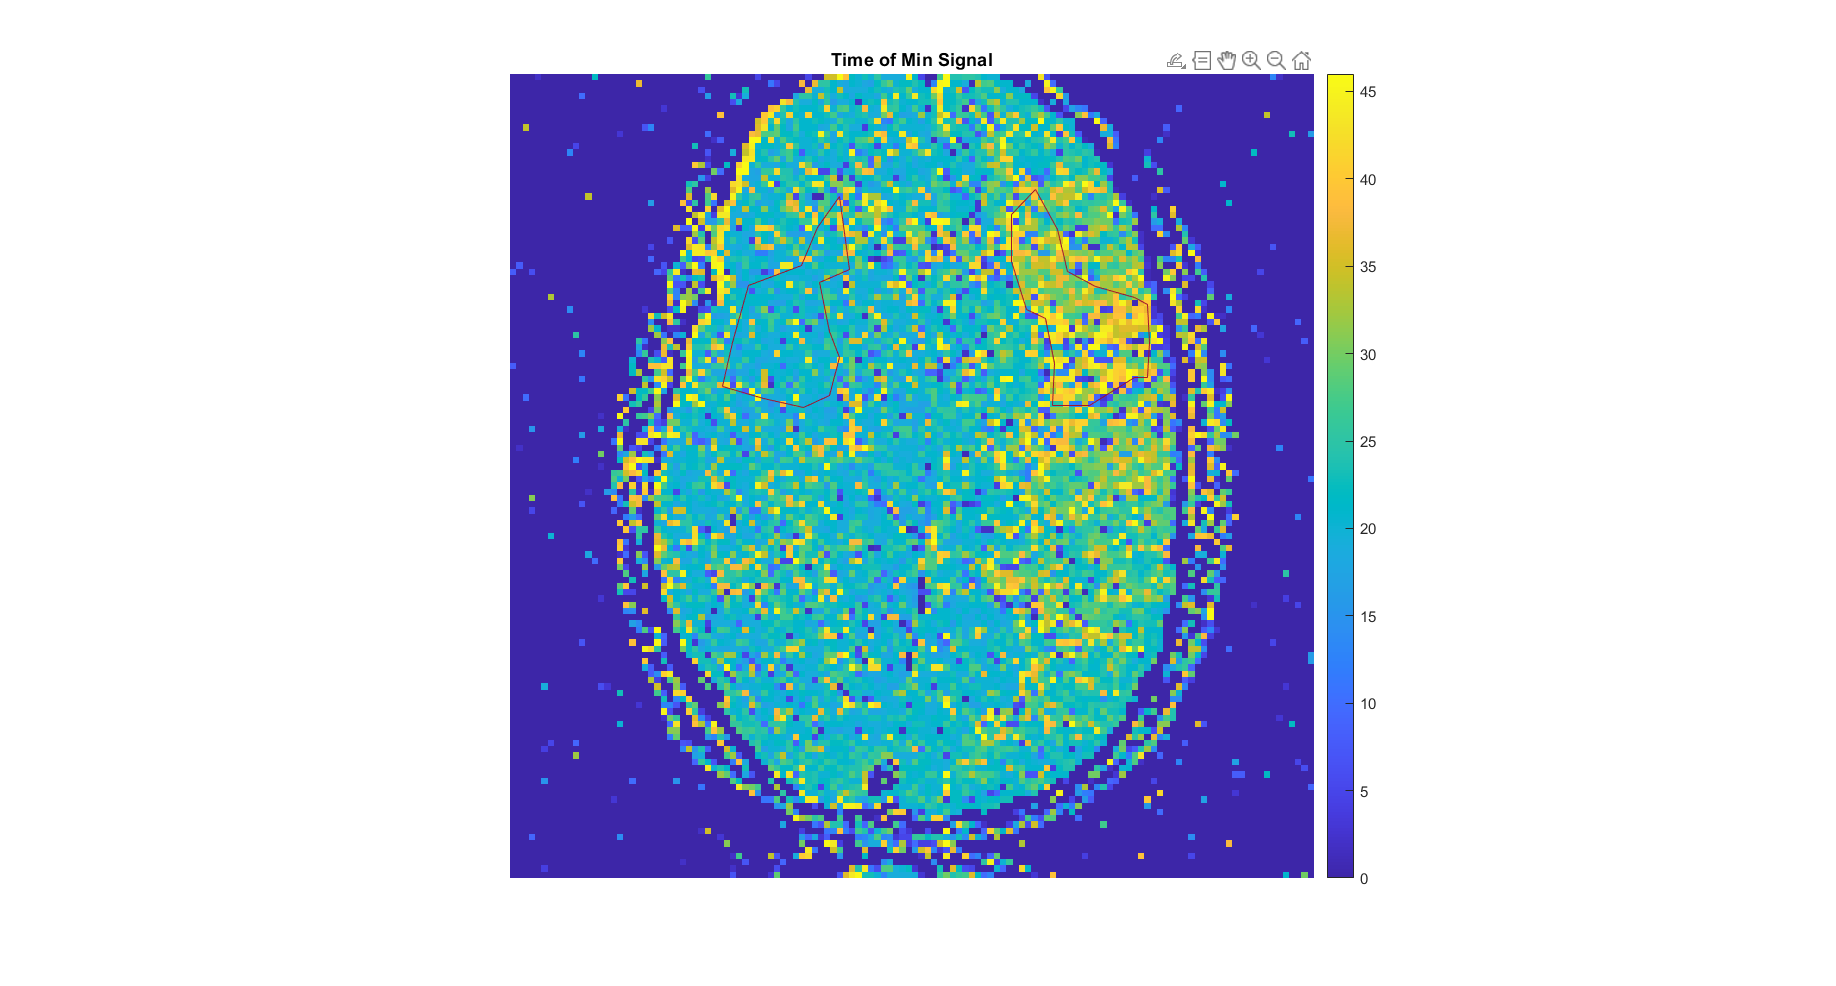

[controlRoiMask_m, xc_v, yc_v] = roipoly ;
controlRoiMask_m = controlRoiMask_m .* headMask_m;
line(xc_v, yc_v, 'Color', '#A2142F') ;

slowRoiMean_v = zeros(1, nTimes);
controlRoiMean_v = zeros(1, nTimes);
for timeIndex = 1:nTimes
    image_m = squeeze(image_3d(:, :, timeIndex));
    numelSlow = sum(sum(slowRoiMask_m));
    numelControl = sum(sum(controlRoiMask_m));
    slowRoi_m = image_m.* slowRoiMask_m;
    controlRoi_m = image_m.* controlRoiMask_m;
    % Enter your own code here to calculate the mean signal
    % in each ROI at the current time:
    slowRoiMean_v(timeIndex) =  sum(sum(slowRoi_m))./numelSlow;
    controlRoiMean_v(timeIndex) = sum(sum(controlRoi_m))./numelControl;
end

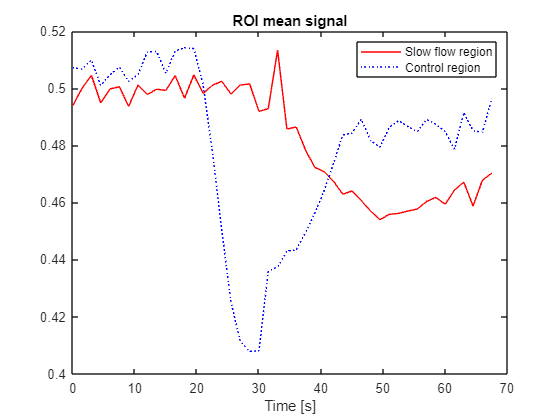

figure
time_v = tr * (0:(nTimes-1));
plot(time_v, slowRoiMean_v, 'r-', time_v, controlRoiMean_v, 'b:')
title('ROI mean signal')
xlabel('Time [s]')
legend('Slow flow region', 'Control region')

baselineTime = input('Enter the duration of the baseline (in seconds): '); %20s
baseIndex_v = find(time_v < baselineTime);
slowBaseSignal = mean(slowRoiMean_v(baseIndex_v));
controlBaseSignal = mean(controlRoiMean_v(baseIndex_v)); 

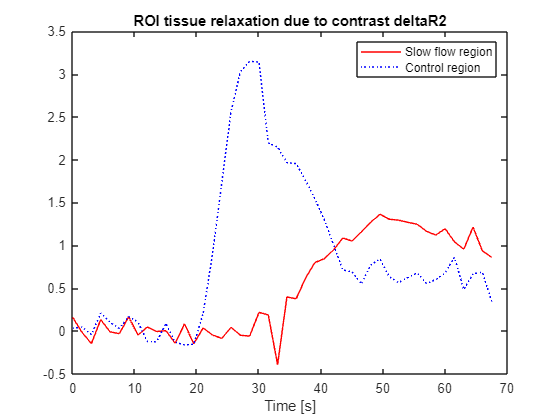

slowR2_v = -log(slowRoiMean_v/slowBaseSignal)/te;
controlR2_v = -log(controlRoiMean_v/controlBaseSignal)/te;

figure
time_v = tr * (0:(nTimes-1));
plot(time_v, slowR2_v, 'r-', time_v, controlR2_v, 'b:')
title('ROI tissue relaxation due to contrast deltaR2')
xlabel('Time [s]')
legend('Slow flow region', 'Control region')

slowCBV = trapz(time_v, slowR2_v);
controlCBV = trapz(time_v,controlR2_v);
relativeCBV = slowCBV/controlCBV

relativeCBV = 0.5798